# Applying the Lawler-Fujita algorithm and distortion subtraction by Gao et al. (2017) to real STM images

This is another attempt in calculating the displacement field in real STM images with the specific goal of examining the performance of the Lawler-Fujita algorithm and distortion subtraction to elucidate the physical strain present in the real sample.

The new function undistort() is also employed here.

## 1    Importing an image

% [~, lattice] = loadsxm('FeSe_Topos_025.sxm', 1);

lattice = double(im2gray(imread('lawler.png')));

name = "lawler";

#### Image specifications

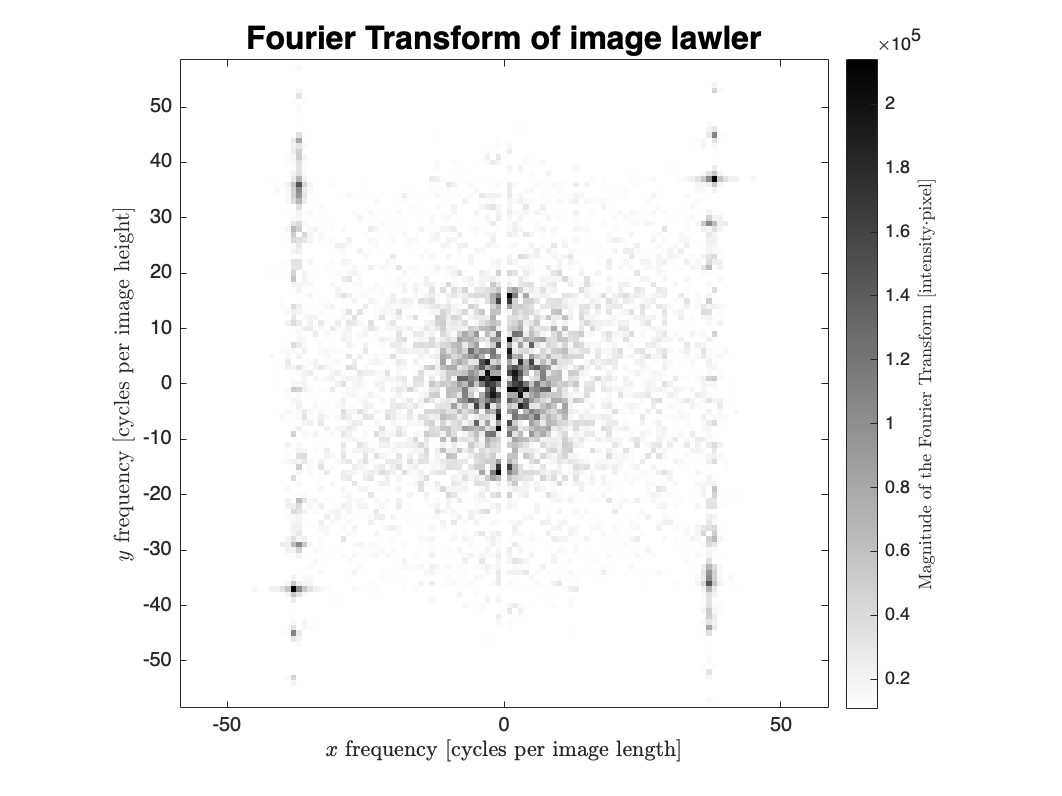

[image_height, image_length] = size(lattice);
lattice = reshape(normalize(lattice(:)),image_height,image_length);

lattice = (lattice-mean(lattice,2))./std(lattice,1,2);
% normalize per row. Adapted from Kirsty's topo042401.m

[lattice_fft, Q_x] = myFFT(lattice,name,[],[],'linear');

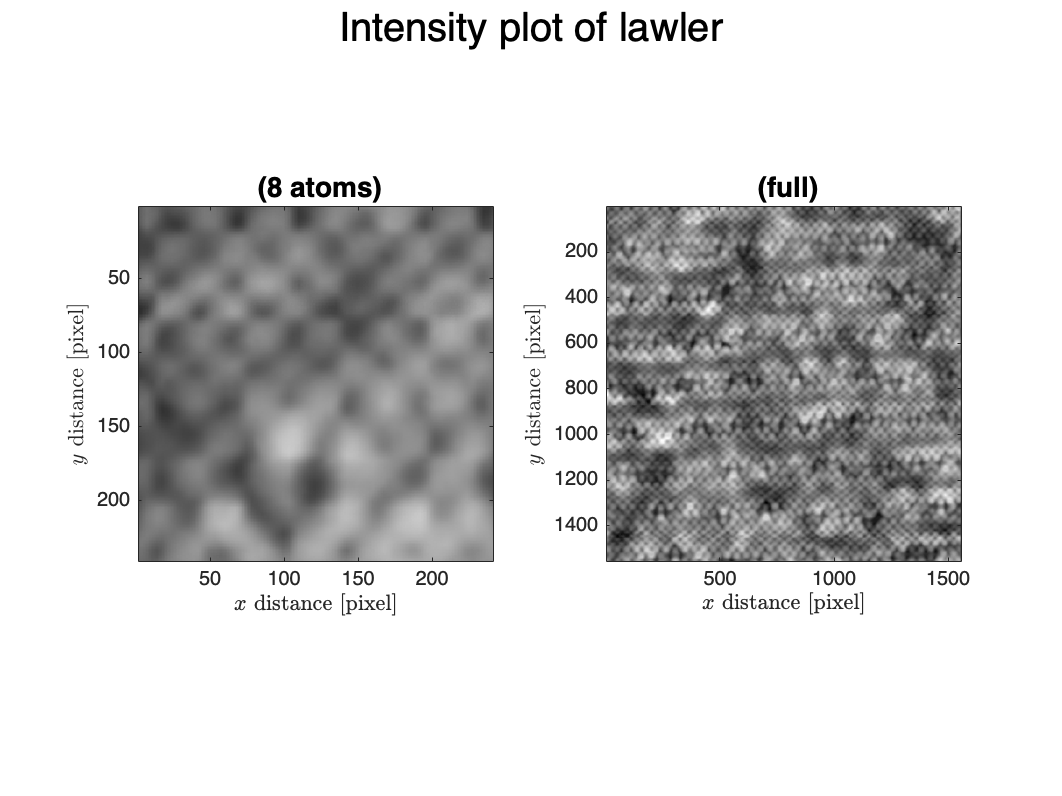


atom_diameter = 1/sqrt((Q_x(1)/image_length)^2+(Q_x(2)/image_height)^2); % [pixel]

comboPlot(lattice,name,atom_diameter);


% distortion, noise, proportion weights in selecting lambda
lambda_scoring_weights = [1 1 0.05];

Q_y = [-Q_x(2) Q_x(1)]; % just to ensure orthogonality
disp("Q_x = (" + Q_x(1) + ", " +  Q_x(2) + ...
    ") and Q_y = (" + Q_y(1) + ", " +  Q_y(2) + ") [FFT units]");

Q_x = (37, 36) and Q_y = (-36, 37) [FFT units]


disp("Lattice constant a = " + atom_diameter + " [pixel]");

Lattice constant a = 30.1412 [pixel]



confidence_level = 0.9999999;

#### Distortion parameters estimates

drift      =  [5 5; 10 10]; % [atom/scan]
hysteresis =  [2 2; 5 5]; % [atom]
creep      =  [2 2; 5 5]; % [atom]

#### Noise parameters estimates

noise_minimumLength = 15; % [atom]
noise_stdMagnitude = 1; % [atom]

Pre-processing the inputs, converting units. You might probably would't want to edit these.

if image_length==256 && image_height==256
    lambda = lambdaChoose(drift,hysteresis,creep, ...
        noise_minimumLength,noise_stdMagnitude,lambda_scoring_weights); % [atom^-1]
    % works only for 256 by 256 images
else
    lambda = 0.2;
end

disp("Lambda used = " + lambda);

Lambda used = 0.2



lambda = lambda*2*pi/atom_diameter;
Q_x = Q_x * 2*pi / (norm(Q_x)*atom_diameter);
Q_y = Q_y * 2*pi / (norm(Q_y)*atom_diameter);
zscore = zscorer(confidence_level);

## 2    Calculating total distortion

Using the Lawler-Fujita algorithm, the total distortion as the sum of the imaging distortion and the physical strain, $\vec{u}_{calc}=\vec{d}+\vec{s}$, is calculated. The effects of noise and the magnitude and type of tolerable distortion could be studied using the previous and the following code.

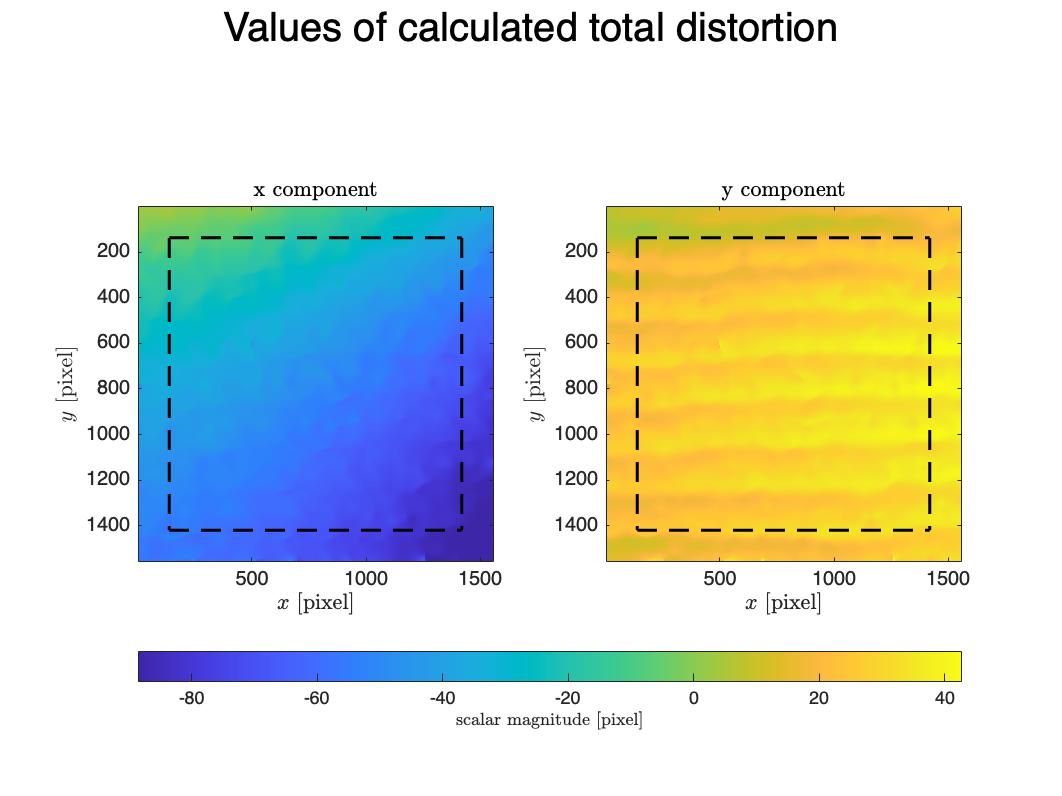

ucalc = myConv(lattice,Q_x,Q_y,lambda,zscore,true); % true as last argument to plot u_x and u_y

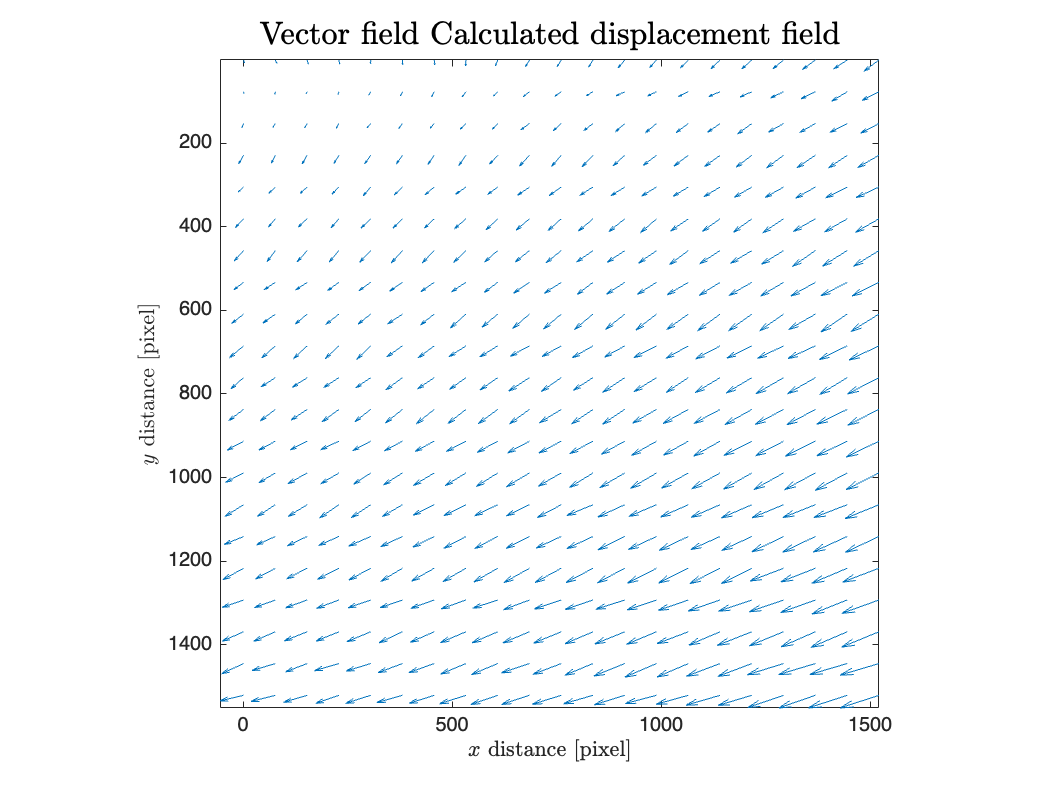


uPlot(ucalc,"Calculated displacement field");


if image_length-2*ceil(zscore/lambda)<=0 && image_height-2*ceil(zscore/lambda)<=0
    error("ERROR! No pixels without padded zeros remain.");
else
    npixel = (image_length-2*ceil(zscore/lambda))*(image_height-2*ceil(zscore/lambda));
    % the number of pixels averaged
    disp("Number of pixels averaged: " + npixel + " (" + ...
        npixel/(image_length*image_height)*100 + "%)");
end

Number of pixels averaged: 1643524 (67.8823%)


## 3    Calculating physical strain

From the equation given above, the physical strain can be obtained by subtracting the smooth, third-digree polynomial imaging distortion from the total distortion.

[fitresultx, gofx,outputx] = createFit(ucalc(:,:,1), lambda,zscore);

Doing polynomial fit using MATLAB's poly33.


% fitPlot(fitresultx, ucalc(:,:,1), "$u_x$", lambda,zscore);
[fitresulty, gofy,outputy] = createFit(ucalc(:,:,2), lambda,zscore);

Doing polynomial fit using MATLAB's poly33.


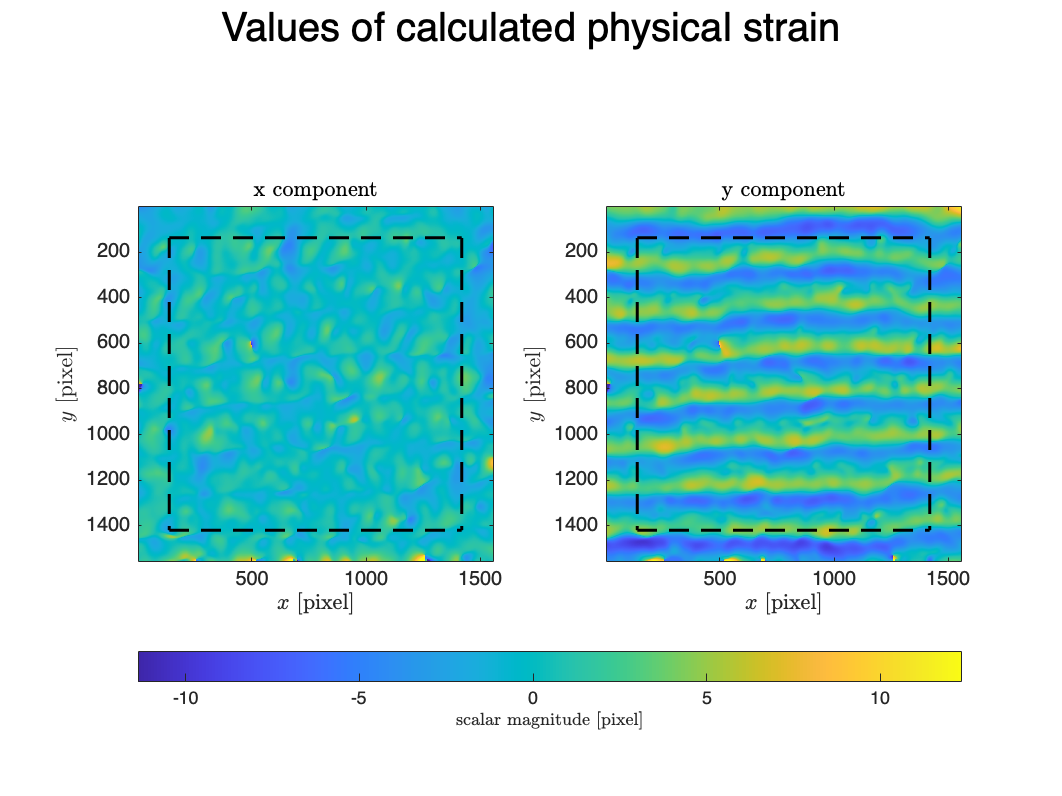

% fitPlot(fitresulty, ucalc(:,:,2), "$u_y$", lambda,zscore);

resx = outputx.residuals/atom_diameter;
resy = outputy.residuals/atom_diameter;
mu = zeros(2,1); sigma = zeros(2,1);
mu(1) = mean(resx); % [lattice constant]
sigma(1) = std(resx,1); % [lattice constant]
mu(2) = mean(resy); % [lattice constant]
sigma(2) = std(resy,1); % [lattice constant]

% to adjust for the [0,1] range of coordinates x,y,t
% and to avoid 'bad equation condition' warning
[xi,yi] = meshgrid(0:1/image_length:(image_length-1)/image_length ...
    ,0:1/image_height:(image_height-1)/image_height);

strain = zeros(size(ucalc));
strain(:,:,1) = ucalc(:,:,1)-fitresultx(xi,yi);
strain(:,:,2) = ucalc(:,:,2)-fitresulty(xi,yi);

convPlot(strain(:,:,1),"calculated physical strain",strain(:,:,2),lambda,zscore);


disp("Physical strain along x = " + (sigma(1)) + " [lattice constant]");

Physical strain along x = 0.042838 [lattice constant]


disp("Physical strain along y = " + (sigma(2)) + " [lattice constant]");

Physical strain along y = 0.10969 [lattice constant]


The strain and it's first order partial derivatives are calculated and plotted. Biaxial and approximate uniaxial strain maps are also generated from the previous calculations.

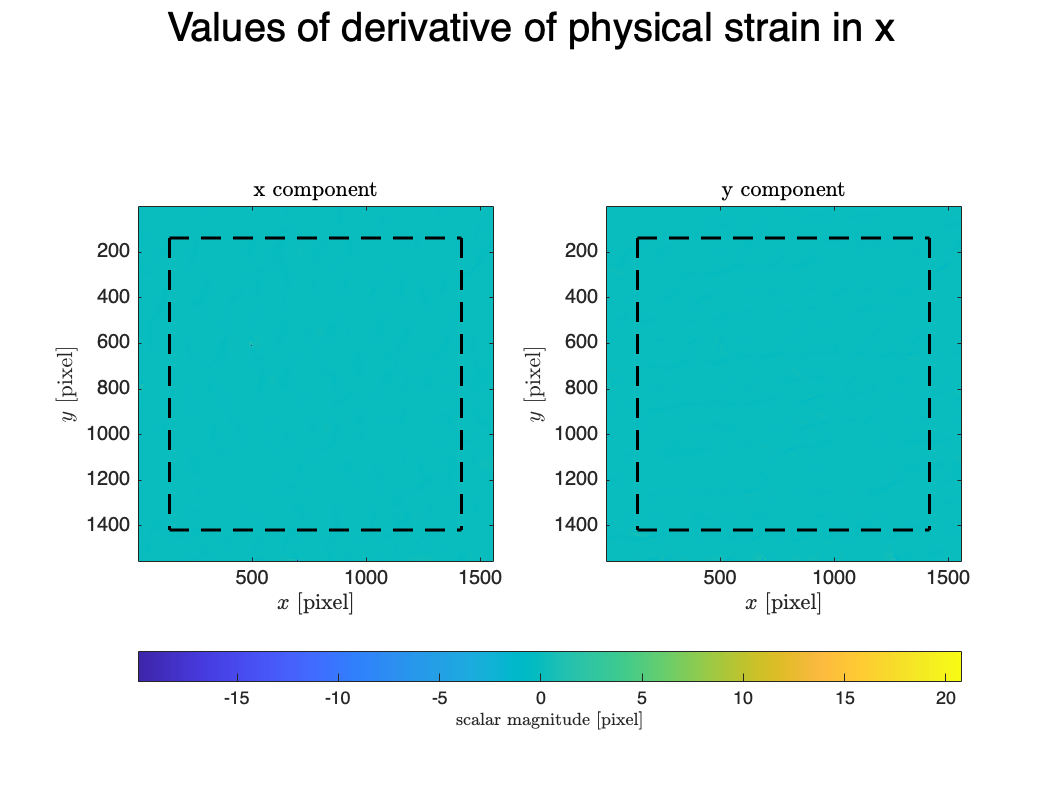

Sxdx = diff(strain(1:end-1,:,1),1,2);
Sxdy = diff(strain(:,1:end-1,1));
Sydx = diff(strain(1:end-1,:,2),1,2);
Sydy = diff(strain(:,1:end-1,2));
convPlot(Sxdx,"derivative of physical strain in x",Sxdy,lambda,zscore);

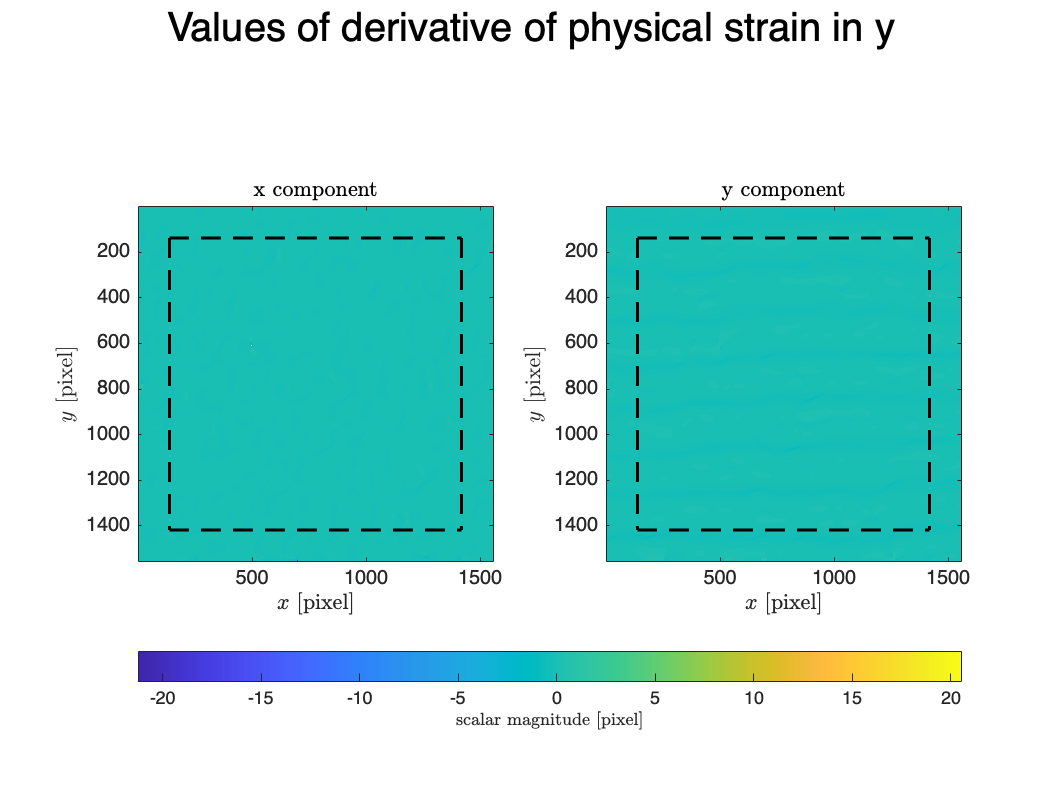

convPlot(Sydx,"derivative of physical strain in y",Sydy,lambda,zscore);

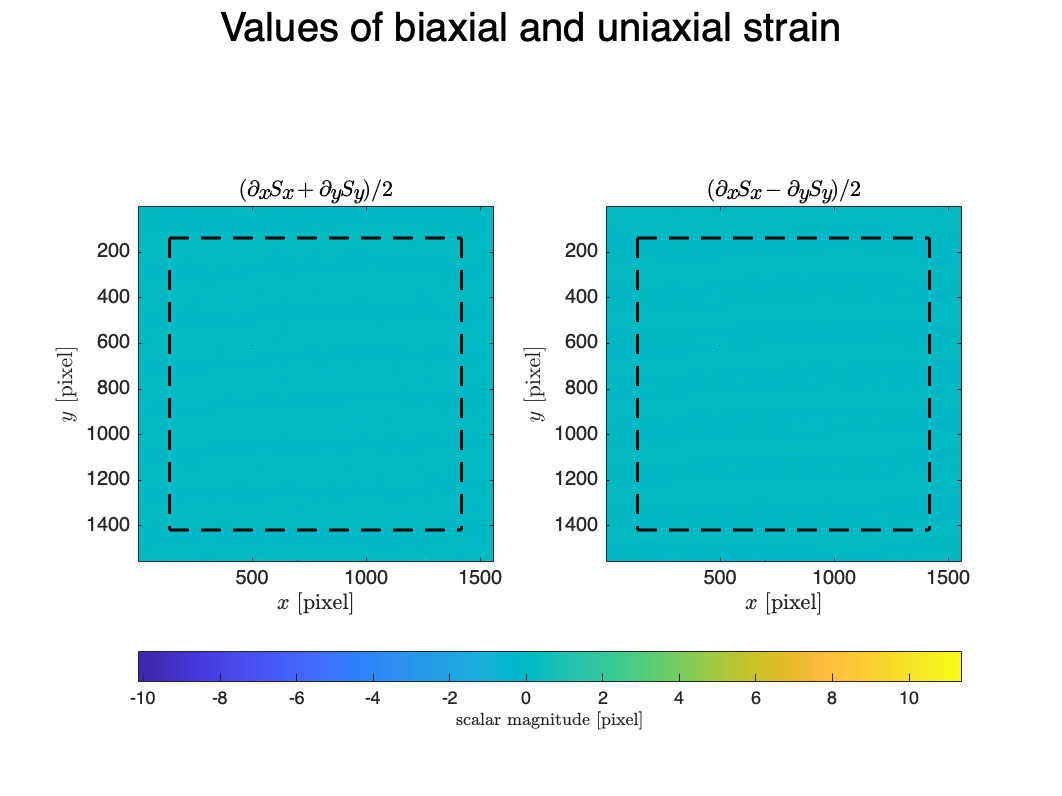

convPlot((Sxdx+Sydy)/2,"biaxial and uniaxial strain",(Sxdx-Sydy)/2,lambda,zscore);

## 4    Undistorting the image

Lastly, we undistort the image using my own undistort() function that in turn uses the imwarpConverse() function that I also built.

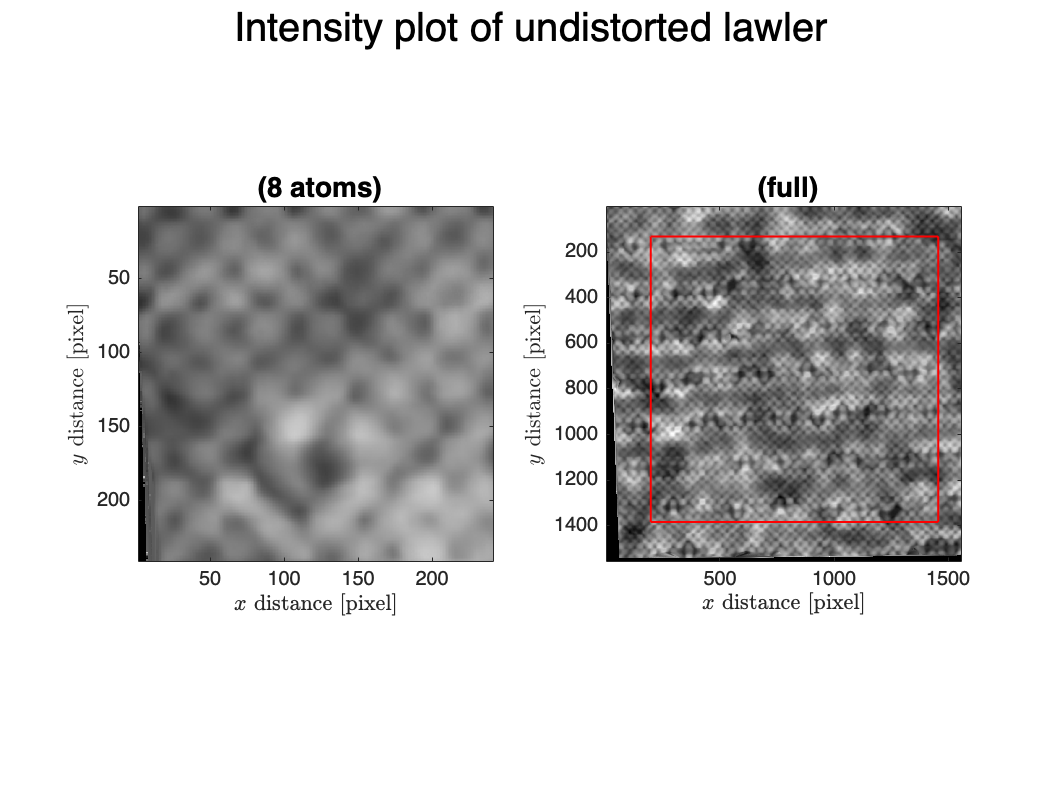

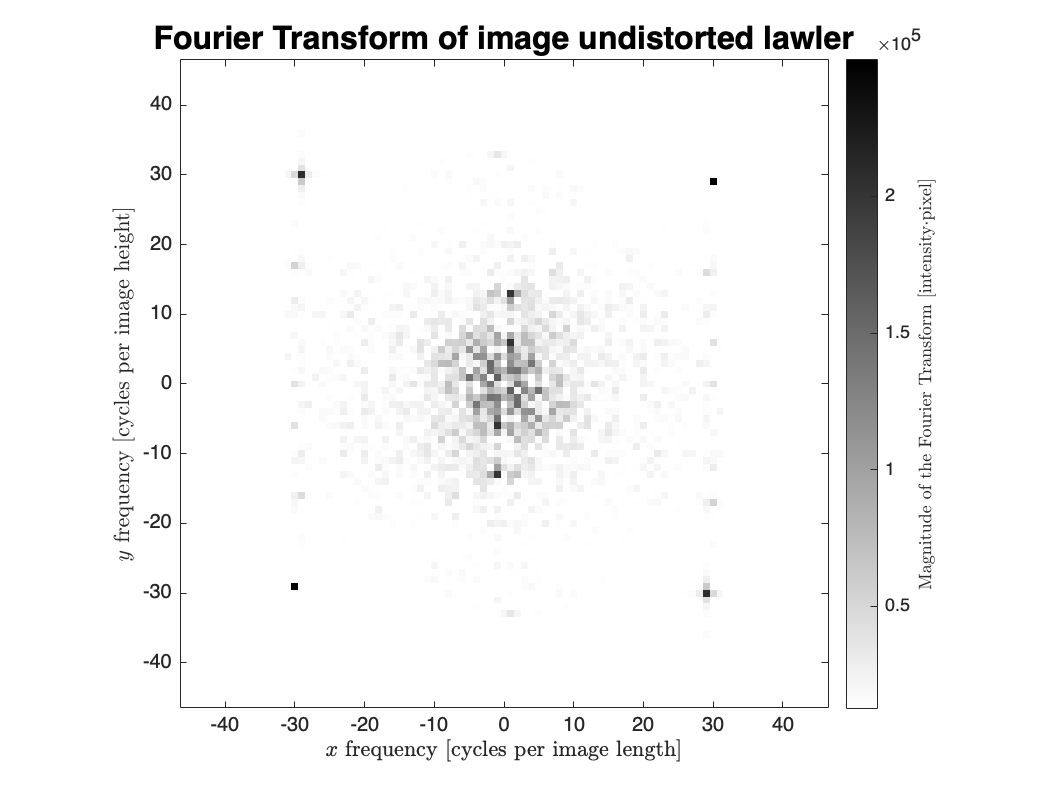

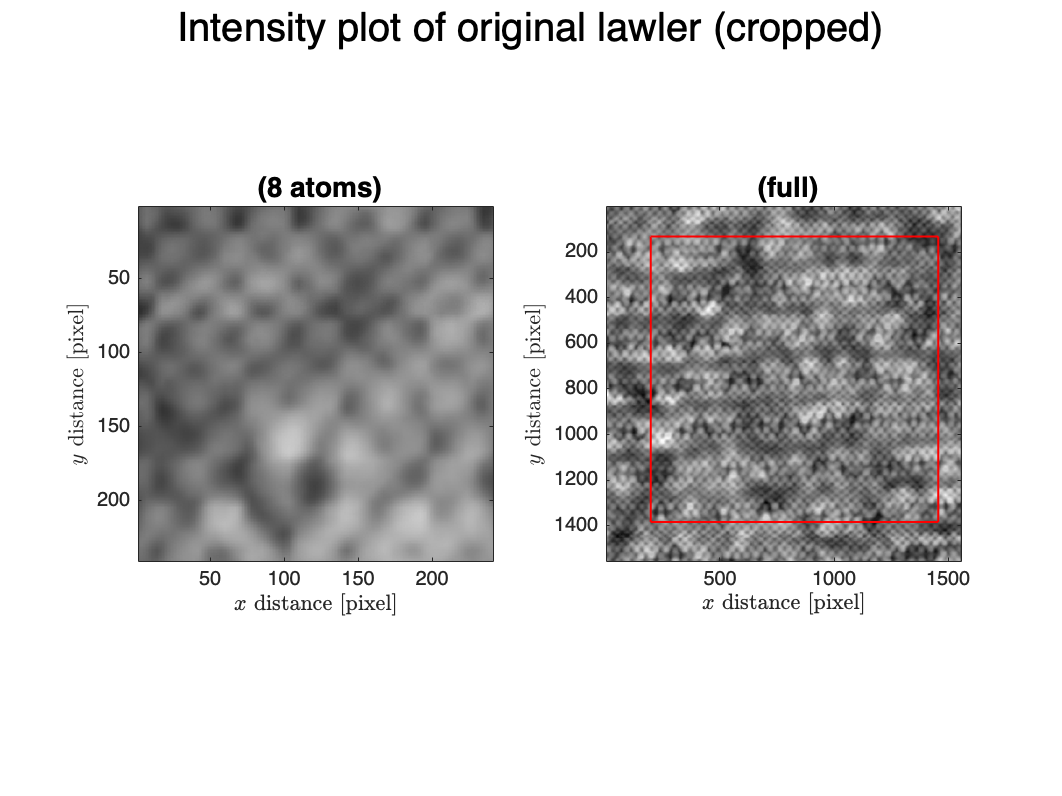

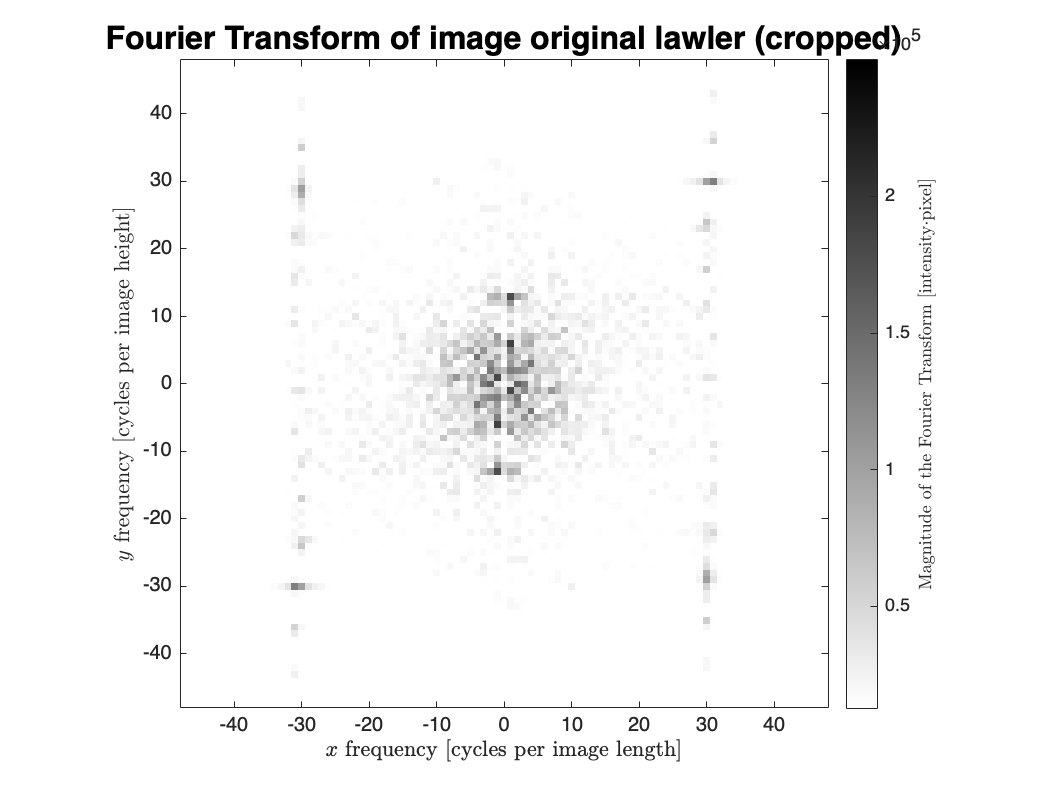

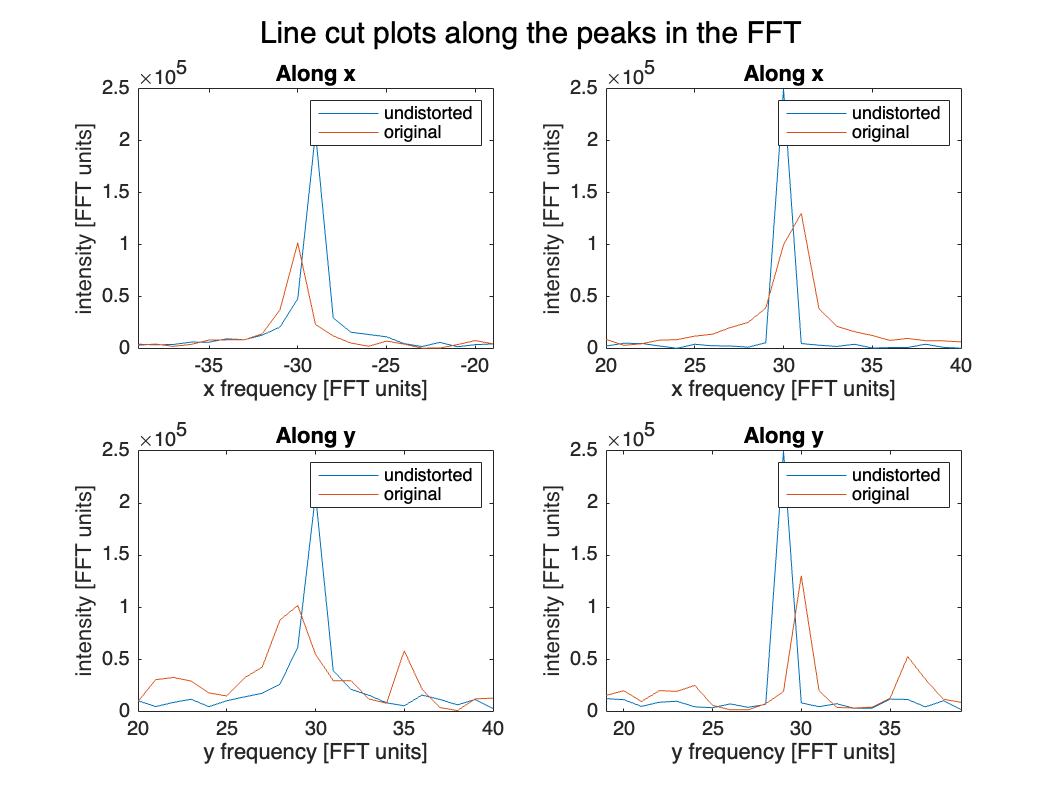

ulattice = undistort(lattice,-ucalc,atom_diameter,lambda,zscore, ...
    [],'linear', ...
    "undistorted " + name , "original " + name + " (cropped)",true);

    % set true as last argument to show line cuts along peaks